# **Project Machine Learning - Scope Classification**

## Loading Data

clear all
load project.mat
fs = 50e3;
section_len = 5e3;

## Training The Models

mdlLoss = 1.6081e-04

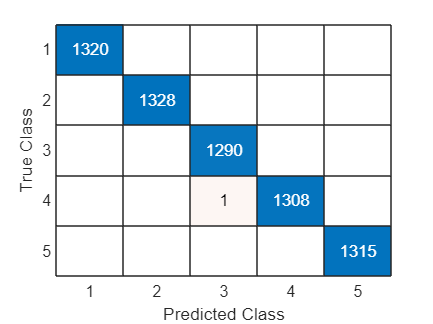

[mdl, norm_center, norm_scale] = getMdl(train1,train2,train3,train4,train5,fs,section_len);

## Getting The Prediction

prediction = zeros(150,1);
for i = 1:length(test)
    prediction(i) = mdlPredict(test{i}(1:section_len),mdl,norm_center,norm_scale,fs);
end

### saving the predictions

save('ytest','prediction') 

## Feature Visualization

### Auto Correlation

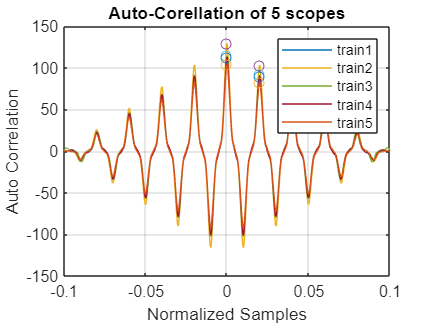

plotAutoCorrelation(train1,train2,train3,train4,train5)

### PSD

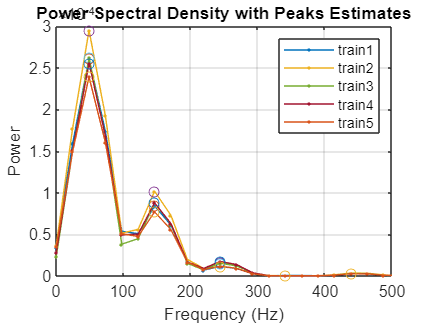

plotPSD(train1,train2,train3,train4,train5)

### Fourier Transform

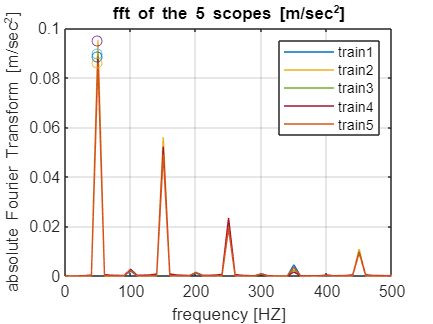

plotFFT(train1,train2,train3,train4,train5)